fprintf("1.")

1.

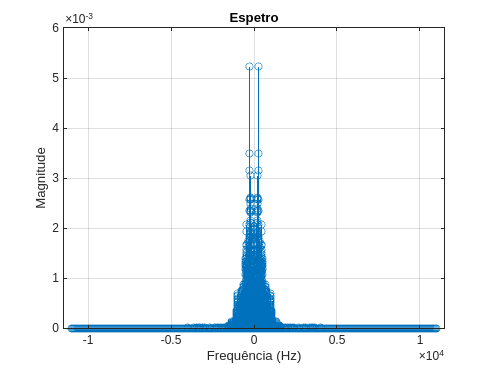

load("Guitar03.mat");
soundsc(x,fa);
ta = 1/fa;
Espetro(x,ta);

2.

Executar no terminal:

>> teta=2*pi*(5000/fa); 

>> xr=x+ 0.6*cos(teta*(0:length(x)-1)'+0.1*pi);

teta=2*pi*(5000/fa);  
xr=x+ 0.6*cos(teta*(0:length(x)-1)'+0.1*pi);
fprintf("2.")

2.

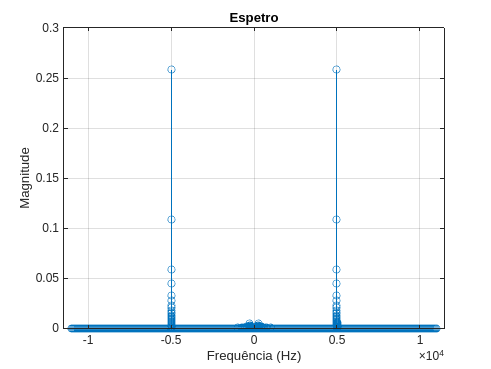

soundsc(xr,fa); %pelo bem dos vossos ouvidos não ouçam isto
Espetro(xr,ta);

3.

Executar no terminal:

R=0.9; teta=2*pi*(5000/fa);

num=[1 -2*cos(teta) 1];

den=[1 -2*R*cos(teta) R^2];

a.

R=0.9; teta=2*pi*(5000/fa); 
num=[1 -2*cos(teta) 1]; 
den=[1 -2*R*cos(teta) R^2];
fprintf("3. a.")

3. a.

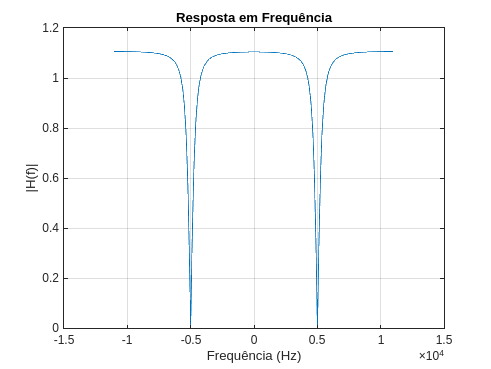

[H, Frequency] = respfreq(num, den, fa);

b.

fprintf("b.")

b.

[H, Frequency] = respfreq(num, den, fa);

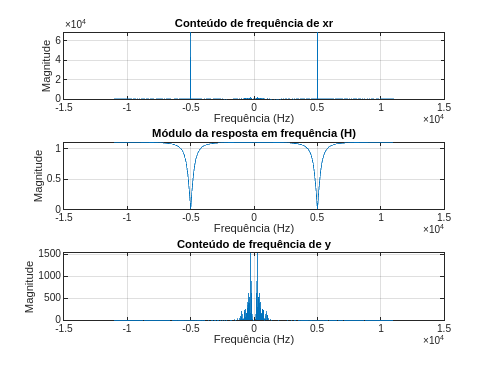

y = filter(num, den, xr);
figure;

subplot(3,1,1);
f_xr = linspace(-fa/2, fa/2, length(xr));
plot(f_xr, abs(fftshift(fft(xr))));
title('Conteúdo de frequência de xr');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
grid on;

subplot(3,1,2);
plot(Frequency, abs(H));
title('Módulo da resposta em frequência (H)');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
grid on;

subplot(3,1,3);
f_y = linspace(-fa/2, fa/2, length(y));
plot(f_y, abs(fftshift(fft(y))));
title('Conteúdo de frequência de y');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
grid on;


sound(y, fa); %mais uma vez, precaução a escutar


c.

Mudar fa para 1000 hz:

fprintf("c.")

c.

fa = 1000

fa = 1000

Repetir alínea b.

Não se ouve nada, pois a frequência é muito baixa.

4.

a)

>>num=[1 zeros(1,D-1) a]; den=1

fprintf("4. a)")

4. a)

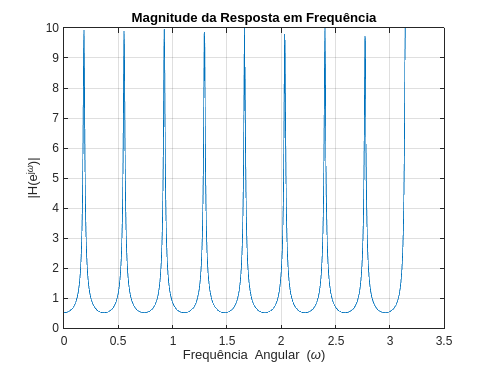

a = 0.9;
D = 17; 

num=[1 zeros(1,D-1) a]; 
den=1;


omega = linspace(0, pi, 1000); % Frequências de 0 a pi
H = 1 ./ (1 + a * exp(-1i * D * omega));

figure;
plot(omega, abs(H));
ylim([0,10]);
title('Magnitude da Resposta em Frequência');
xlabel('Frequência Angular (\omega)');
ylabel('|H(e^{j\omega})|');
grid on;

b)

fprintf("b)")

b)

distancia_minima = 17; 
velocidade_som = 340; %m/s
taxa_amostragem = 44100; 

D = round((distancia_minima / velocidade_som) * taxa_amostragem);

disp(['Valor calculado para D: ' num2str(D)]);

Valor calculado para D: 2205


Simulação do sistema/filtro para a=0.9:

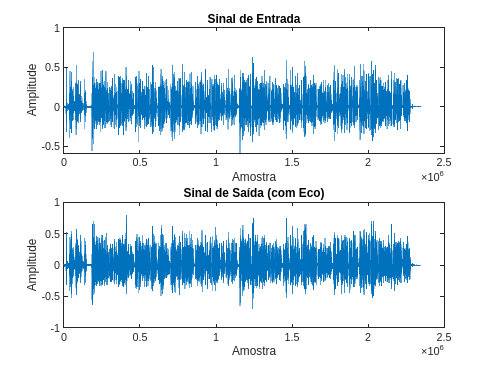

load('Guitar03.mat');
[x, fa] = audioread('vozportugues.wav');

% Definir a função de transferência
num = [1 zeros(1, D-1) a];
den = 1;

y = filter(num, den, x);

figure;
subplot(2,1,1);
plot(x);
title('Sinal de Entrada');
xlabel('Amostra');
ylabel('Amplitude');
subplot(2,1,2);
plot(y);
title('Sinal de Saída (com Eco)');
xlabel('Amostra');
ylabel('Amplitude');


soundsc(x, fa); % Sinal de entrada
pause(length(x)/fa);
soundsc(y, fa); % Sinal de saída com eco

c) Fazer em papel, cenas de Cálculo II

d) 

fprintf("d)")

d)

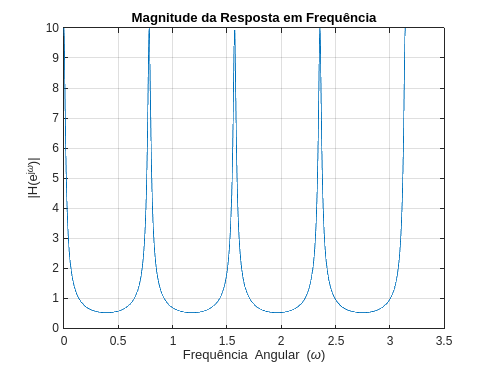

D = 8;
a = 0.9;

omega = linspace(0, pi, 1000); % Frequências de 0 a pi
H = 1 ./ (1 - a * exp(-1i * D * omega));

figure;
plot(omega, abs(H));
title('Magnitude da Resposta em Frequência');
xlabel('Frequência Angular (\omega)');
ylabel('|H(e^{j\omega})|');
grid on;

e)

fprintf("e)")

e)

a = 0.9;
atraso = 10; % Atraso em ms
D = round((atraso / 1000) * fa)

D = 221

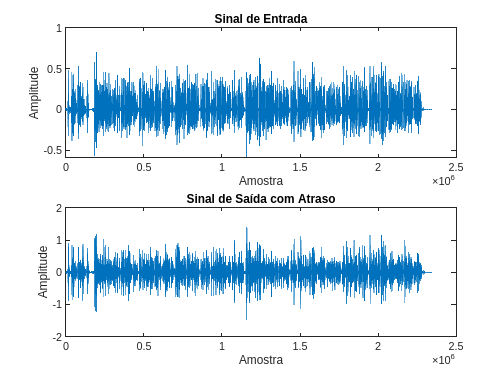


% Criar a função de transferência
num = 1;
den = [1 zeros(1, D - 1) a];

y = filter(num, den, x);

figure;
subplot(2,1,1);
plot(x);
title('Sinal de Entrada');
xlabel('Amostra');
ylabel('Amplitude');
subplot(2,1,2);
plot(y);
title('Sinal de Saída com Atraso');
xlabel('Amostra');
ylabel('Amplitude');


sound(x, fa); % Sinal de entrada
pause(length(x)/fa);
sound(y, fa); % Sinal de saída com atraso

Função Resposta em Frequência:

function [H,f]=respfreq(num,den,fa)

    N = 1000;
    H = freqz(num,den,N,fa,'whole'); 
    H = abs(fftshift(H));

    f = (-N/2 : N/2-1)*(fa/N);

    plot(f, H);
    title('Resposta em Frequência');
    xlabel('Frequência (Hz)');
    ylabel('|H(f)|');
    grid on;
end